# **Exercise n°1-2**

clc
clear

- ** Part 1:**

Parameters:

x_i = 0; y_i = 0; theta_i = 0;
l = 1;

%%% Computation of final coordinates
a = rand(1,3); % generation of vector 1x3 of random values
q_f = a./norm(a,2) % because ||q_f - q_i||=1 is satisfied always in this way

q_f =     0.5010    0.8373    0.2187


x_f = q_f(1,1); y_f = q_f(1,2); theta_f = q_f(1,3);

%%% Parameters of Cartesian cubic polynomial
k = 1 % by choosing k_i=k_f to reduce the number of degrees of freedom

k = 1

if k == 0
    disp('Value of k not valid!')
end

ds = 0.001;
s = 0:ds:l; % the time law is simply s(t)=t/T in this case

alpha_x = k*cos(theta_f) - 3*x_f;
alpha_y = k*sin(theta_f) - 3*y_f;
beta_x = k*cos(theta_i) + 3*x_i;
beta_y = k*sin(theta_i) + 3*y_i;

%%% Parameters for time law
v_max = 0.5; % m/s
w_max = 2; %rad/s

Cubic Cartesian polynomial:

x_s = s.^3.*x_f-(s-1).^3.*x_i+alpha_x.*s.^2.*(s-1)+beta_x.*s.*(s-1).^2;
y_s = s.^3.*y_f-(s-1).^3.*y_i+alpha_y.*s.^2.*(s-1)+beta_y.*s.*(s-1).^2;

With the flat outputs it's possible to reconstruct the inputs and to compute the angular motion.

It must need the prime derivatives and second derivatives of the cubic Cartesian polynomial:

x_s_prime = 3.*s.^2*x_f-3.*(s-1).^2*x_i+alpha_x.*(3.*s.^2-2.*s)+beta_x.*(s-1).^2+beta_x.*s*2.*(s-1);
y_s_prime = 3.*s.^2*y_f-3.*(s-1).^2*y_i+alpha_y.*(3.*s.^2-2.*s)+beta_y.*(s-1).^2+beta_y.*s*2.*(s-1);
x_s_sec = 6.*s*x_f-6*(s-1)*x_i+alpha_x.*(6.*s-2)+beta_x*2.*(s-1)+beta_x*2.*(2.*s-1);
y_s_sec = 6.*s*y_f-6*(s-1)*y_i+alpha_y.*(6.*s-2)+beta_y*2.*(s-1)+beta_y*2.*(2.*s-1);

%supposing forward motion
theta_s = atan2(y_s_prime,x_s_prime);
v_tilde_s = sqrt(x_s_prime.^2 + y_s_prime.^2);
w_tilde_s = (y_s_sec.*x_s_prime - x_s_sec.*y_s_prime)./(x_s_prime.^2 + y_s_prime.^2);

Plot of the **desired trajectory path** and of the **desired orientation**:

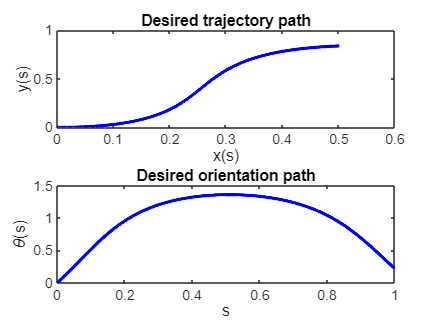

figure(1)
subplot(2,1,1)
plot(x_s,y_s,'b','LineWidth',2)
title('Desired trajectory path')
xlabel('x(s)')
ylabel('y(s)')

subplot(2,1,2)
plot(s, theta_s,'b','LineWidth',2)
title('Desired orientation path')
xlabel('s')
ylabel('\theta(s)')

Computation of control inputs (desired heading velocity and angular velociities) respect to flat output and respect to the time:

t_i = 0

t_i = 0

t_f = 5

t_f = 5

T = t_f - t_i

T = 5

dt=T/(size(s,2)-1); % because t must need the same dimension of elements of s
dtau= dt/T;

t=t_i:dt:t_f;
s_dot = ds/dt;
v_t = v_tilde_s*s_dot

v_t =     0.2000    0.1994    0.1988    0.1983    0.1977    0.1971    0.1966    0.1960    0.1955    0.1949    0.1944    0.1938    0.1933    0.1928    0.1923    0.1918    0.1913    0.1908    0.1903    0.1898    0.1893    0.1888    0.1884    0.1879    0.1874    0.1870    0.1865    0.1861    0.1857    0.1852    0.1848    0.1844    0.1840    0.1836    0.1831    0.1828    0.1824    0.1820    0.1816    0.1812    0.1808    0.1805    0.1801    0.1798    0.1794    0.1791    0.1788    0.1784    0.1781    0.1778


w_t = w_tilde_s*s_dot

w_t =     0.9180    0.9217    0.9253    0.9289    0.9325    0.9360    0.9395    0.9430    0.9465    0.9499    0.9534    0.9567    0.9601    0.9634    0.9667    0.9699    0.9731    0.9763    0.9794    0.9825    0.9856    0.9886    0.9915    0.9945    0.9974    1.0002    1.0030    1.0057    1.0084    1.0111    1.0137    1.0163    1.0188    1.0212    1.0237    1.0260    1.0283    1.0306    1.0327    1.0349    1.0370    1.0390    1.0410    1.0429    1.0447    1.0465    1.0482    1.0499    1.0515    1.0530


Verification of the control inputs limits:

for i = 1:size(v_t,2)
    if v_t(1,i) > v_max
        T = (v_tilde_s(1,i)*ds/dtau)/v_max % new increased T
        
        t_f = t_i + T% new final time
        dt=T/(size(s,2)-1); % new dt
        dtau = dt/T % new tau

        t = t_i:dt:t_f; % new time interval
        s_dot = ds/dt; % new s_dot
        v_t = v_tilde_s*ds/dtau*1/T % new heading velocity in time
        w_t = w_tilde_s*ds/dtau*1/T % new angular velocity in time
    end
end
for j = 1:size(w_t,2)
    if w_t(1,i) > w_max
        T = (v_tilde_s(1,i)*ds/dtau)/v_max % new increased tau
        t_f = T - t_i % new final time
        dt=T/(size(s,2)-1);
        dtau = dt/T % new tau

        t = t_i:dt:t_f; % new time interval
        s_dot = ds/dt; % new s_dot
        v_t = v_tilde_s*ds/dtau*1/T % new heading velocity in time
        w_t = w_tilde_s*ds/dtau*1/T % new angular velocity in time
    end
end

Desired heading velocity and angular velocity plots:

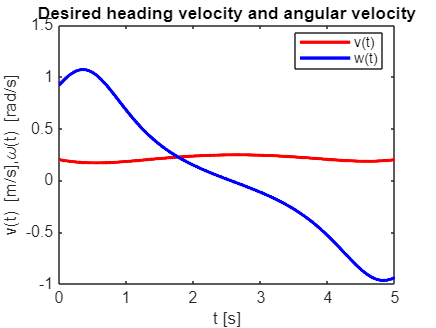

figure(2)
plot(t, v_t,'r', t, w_t, 'b','LineWidth',2)
title('Desired heading velocity and angular velocity')
xlabel('t [s]')
ylabel('v(t) [m/s],\omega(t) [rad/s]')
legend('v(t)','w(t)','Location','best')

- Part 2:

Parameters:

b = 0.01; % distance of the new point B from the center of the unicycle in the sagittal plane

k_1 = 50; k_2 = 50; % controller gains

if b == 0
    disp('Choose a value of distance b different from 0.')
elseif k_1 <= 0 || k_2 <= 0
    disp('Not valid gains.')
else
    % coordinates of B
    y_1 = zeros(size(s));
    y_2 = zeros(size(s));
    y_1(1,1) = x_i + b*cos(theta_i);
    y_2(1,1) = y_i + b*sin(theta_i);

    %real theta
    theta_r = zeros(size(s));
    theta_r(1,1) = theta_i;

    %real heading velocity and angular velocities
    v_r = zeros(size(s));
    w_r = zeros(size(s)); 
    
    %errors
    e_1 = zeros(size(s));
    e_2 = zeros(size(s));
    e_3 = zeros(size(s));

    %Previous desired coordinates initialization
    y_1d_p = 0;
    y_2d_p = 0;

    for i=2:size(s,2)
        y_1d = x_s(1,i)+b*cos(theta_s(1,i));
        y_2d = y_s(1,i)+b*sin(theta_s(1,i));

        % Derivatives of the desired y_1 and y_2
        y_1d_dot = (y_1d - y_1d_p)/dt;
        y_2d_dot = (y_2d - y_2d_p)/dt;

        % Computation of the error
        e_1(1,i) = y_1d - y_1(1,i-1); 
        e_2(1,i) = y_2d - y_2(1,i-1);
        e_3(1,i) = theta_s(1,i) - theta_r(1,i-1);
        
        % Computations of the control inputs with a simple controller
        u_1 = y_1d_dot + k_1*e_1(1,i);
        u_2 = y_2d_dot + k_2*e_2(1,i);

        % Computation of the output
        T_theta = [cos(theta_r(1,i-1)) -b*cos(theta_r(1,i-1));
            sin(theta_r(1,i-1)) b*cos(theta_r(1,i-1))];
        q = inv(T_theta)*[u_1 u_2]'; %system output vector
        v_r(1,i) = q(1,1);
        w_r(1,i) = q(2,1);

        theta_r(1,i) = theta_r(1,i-1) + w_r(1,i)*ds;
        y_1(1,i) = y_1(1,i-1) + v_r(1,i)*cos(theta_r(1,i))*ds;
        y_2(1,i) = y_2(1,i-1) + v_r(1,i)*sin(theta_r(1,i))*ds;

        %Previous desired coordinates
        y_1d_p = y_1d;
        y_2d_p = y_2d;
    end
end

Differents between the desired trajectory path and the computed one by the controller:

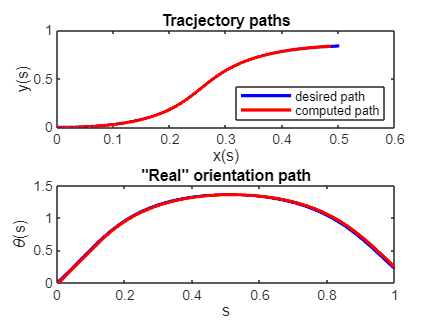

x_r = y_1 - b.*cos(theta_r);
y_r = y_2 - b.*sin(theta_r);
figure(3)
subplot(2,1,1)
plot(x_s,y_s,'b',x_r,y_r,'r','LineWidth',2)
title('Tracjectory paths')
legend('desired path','computed path','Location','best')
xlabel('x(s)')
ylabel('y(s)')

subplot(2,1,2)
plot(s, theta_s,'b',s, theta_r,'r','LineWidth',2)
title('"Real" orientation path')
xlabel('s')
ylabel('\theta(s)')

Error behaviour:

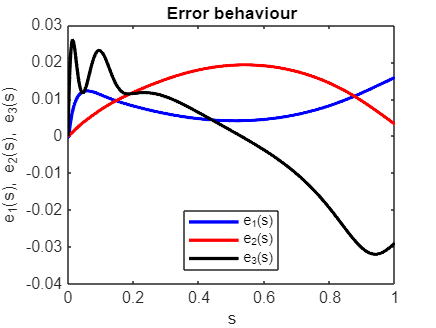

figure(4)
plot(s,e_1,'b',s,e_2,'r',s,e_3,'k','LineWidth',2)
title('Error behaviour')
legend('e_1(s)','e_2(s)','e_3(s)','Location','best')
xlabel('s')
ylabel('e_1(s), e_2(s), e_3(s)')

Obtained heading and angular velocities:

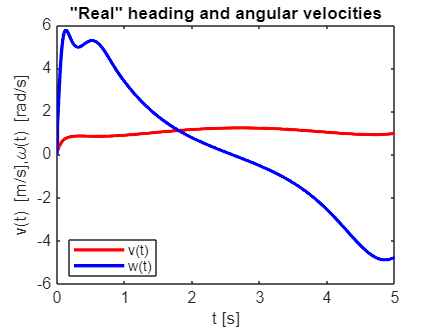

figure(5)
plot(t, v_r,'r', t, w_r, 'b','LineWidth',2)
title('"Real" heading and angular velocities')
xlabel('t [s]')
ylabel('v(t) [m/s],\omega(t) [rad/s]')
legend('v(t)','w(t)','Location','best')